Double pendulum equations of motion

% Options
sympref('AbbreviateOutput', false);

% NB: Notation - use e.g. x_ for coordinate symvars, x(t) for sym functions

% Time variable
syms t;

% Parameters
syms m [2 1];
syms r [2 1];
syms g;

% ALL coordinates using whatever notation (inc generalised, redundant)
syms x_ [2 1];
syms y_ [2 1];
syms theta_ [2 1];

% Derivatives of above coordinates
syms x_dot_ [2 1];
syms y_dot_ [2 1];
syms theta_dot_ [2 1];          % NB: extra _ just for formatting

% Second derivatives, for whichever ones we want in the EOM
syms theta_ddot_ [2 1];          % NB: extra _ just for formatting

% Generalised coordinates (for the Euler-Lagrange derivation)
syms q_ [2 1];
syms q_dot_ [2 1];

% symfuns for generalised coordinates
syms q(t) [2 1];


% Kinematic relationships (positions)
x_(1) = r(1) * sin (theta_(1));
y_(1) = - r(1) * cos (theta_(1));
x_(2) = x_(1) + r(2) * sin (theta_(2));
y_(2) = y_(1) - r(2) * cos (theta_(2));

% Differentiate to find velocities (kinematics, chain rule)
for ii=1:2
    x_dot_(ii) = 0;
    y_dot_(ii) = 0;
    for jj=1:2
        x_dot_(ii) = x_dot_(ii) + diff(x_(ii), theta_(jj)) * theta_dot_(jj);
        y_dot_(ii) = y_dot_(ii) + diff(y_(ii), theta_(jj)) * theta_dot_(jj);
    end
end
x_dot_

$$x\_dot\_ = \left(\begin{array}{c} r_{1}\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)\\ r_{1}\,{\dot{\theta }}_{1}\,\cos\left(\theta_{1}\right)+r_{2}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{2}\right) \end{array}\right)$$

y_dot_

$$y\_dot\_ = \left(\begin{array}{c} r_{1}\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)\\ r_{1}\,{\dot{\theta }}_{1}\,\sin\left(\theta_{1}\right)+r_{2}\,{\dot{\theta }}_{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$


% Kinetic energy
T = 0;
for ii=1:2
    T = T + 1/2*m(ii)*(x_dot_(ii)^2 + y_dot_(ii)^2);      % KE of mass ii
end

% Potential energy
V = 0;
for ii=1:2
    V = V + m(ii) * g * y_(ii);
end


% Lagrangian
L = simplify(T - V)

$$L = \frac{m_{1}\,{r_{1}}^{2}\,{{\dot{\theta }}_{1}}^{2}}{2}+\frac{m_{2}\,{r_{1}}^{2}\,{{\dot{\theta }}_{1}}^{2}}{2}+\frac{m_{2}\,{r_{2}}^{2}\,{{\dot{\theta }}_{2}}^{2}}{2}+g\,m_{1}\,r_{1}\,\cos\left(\theta_{1}\right)+g\,m_{2}\,r_{1}\,\cos\left(\theta_{1}\right)+g\,m_{2}\,r_{2}\,\cos\left(\theta_{2}\right)+m_{2}\,r_{1}\,r_{2}\,{\dot{\theta }}_{1}\,{\dot{\theta }}_{2}\,\cos\left(\theta_{1}-\theta_{2}\right)$$


% Define which variables are our generalised coordinates
q_ = theta_;
q_dot_ = theta_dot_;

% EL-equations - loop to perform all differentiations and collect EOM
eom = [];
for ii=1:2
    Ldx = diff(L,q_(ii));
    Ldv = diff(L,q_dot_(ii));

    % sub symfuns
    Ldx(t) = subs(Ldx, [q_ q_dot_], [q diff(q,t)]);
    Ldv(t) = subs(Ldv, [q_ q_dot_], [q diff(q,t)]);

    % Form Euler-Lagrange equations for system
    Ldvdt(t) = diff(Ldv,t);
    eom = [eom; collect(Ldvdt, diff(q,2)) == collect(simplifyFraction(Ldx),q)];
    
end

% display equations of motion (in original coords)
subs(eom, [q diff(q,1) diff(q,2)], [theta_ theta_dot_ theta_ddot_])

$$ans(t) = \left(\begin{array}{c} 0=-g\,m_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-g\,m_{2}\,r_{1}\,\sin\left(\theta_{1}\right)\\ 0=-g\,m_{2}\,r_{2}\,\sin\left(\theta_{2}\right) \end{array}\right)$$


% Now let's convert the EOMs into first order (state space)
[Ydot, S] = odeToVectorField(eom)

$$Ydot = \left(\begin{array}{c} Y_{2}\\ -\frac{g\,m_{1}\,\sin\left(Y_{1}\right)+g\,m_{2}\,\sin\left(Y_{1}\right)-g\,m_{1}\,\sin\left(Y_{3}\right)\,\cos\left(Y_{1}-Y_{3}\right)-g\,m_{2}\,\sin\left(Y_{3}\right)\,\cos\left(Y_{1}-Y_{3}\right)+m_{1}\,r_{1}\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{4}}^{2}+m_{2}\,r_{1}\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{4}}^{2}+m_{2}\,r_{2}\,\cos\left(Y_{1}-Y_{3}\right)\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{2}}^{2}}{r_{2}\,\left(-m_{2}\,{\cos\left(Y_{1}-Y_{3}\right)}^{2}+m_{1}+m_{2}\right)}\\ Y_{4}\\ \frac{m_{2}\,r_{2}\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{2}}^{2}+m_{2}\,r_{1}\,\cos\left(Y_{1}-Y_{3}\right)\,\sin\left(Y_{1}-Y_{3}\right)\,{Y_{4}}^{2}-g\,m_{1}\,\sin\left(Y_{3}\right)-g\,m_{2}\,\sin\left(Y_{3}\right)+g\,m_{2}\,\sin\left(Y_{1}\right)\,\cos\left(Y_{1}-Y_{3}\right)}{-m_{2}\,r_{1}\,{\cos\left(Y_{1}-Y_{3}\right)}^{2}+m_{1}\,r_{1}+m_{2}\,r_{1}} \end{array}\right)$$

$$S = \left(\begin{array}{c} q_{2}\\ {\mathrm{Dq}}_{2}\\ q_{1}\\ {\mathrm{Dq}}_{1} \end{array}\right)$$

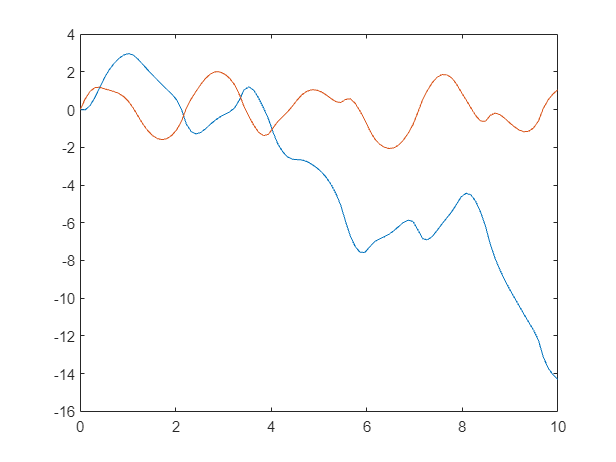


% Let's code generate a MATLAB function for the ODE RHS
pend = matlabFunction(Ydot,'vars',{'t','Y', [g; m; r]});

% Numerical values of parameters
m1 = 1;
m2 = 1;
r1 = 1;
r2 = 1;
g = 9.81;
pars = [g; m1; m2; r1; r2];

% Initial condition
t1_0 = 0;
v1_0 = 6;
t2_0 = 0;
v2_0 = -1;
yInit = [t2_0 v2_0 t1_0 v1_0];

% Solution of IVP using ode45;
interval = [0 10];
ySol = ode45(@(tt,yy) pend(tt,yy,pars), interval, yInit);

% Plot solution
figure(2001); cla;
tValues = linspace(0,10,100);
yValues = deval(ySol,tValues,[1,3]);
plot(tValues,yValues)

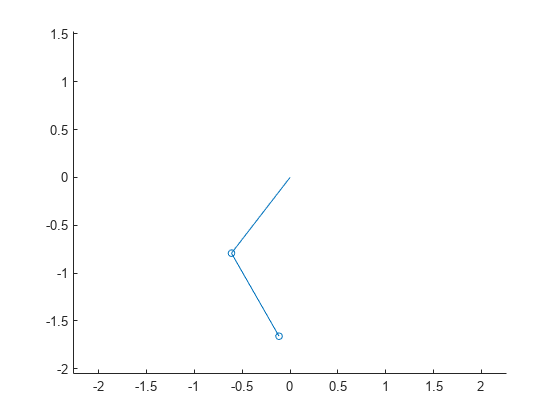


% Visualise solution
x_1 = @(t) r1*sin(deval(ySol,t,3));
y_1 = @(t) -r1*cos(deval(ySol,t,3));
x_2 = @(t) r2*sin(deval(ySol,t,3)) + r2*sin(deval(ySol,t,1));
y_2 = @(t) -r2*cos(deval(ySol,t,3)) - r2*cos(deval(ySol,t,1));

% Set up figure and animate
figure(1001); cla; axis equal; hold on;
fanimator(@(t) plot(x_1(t),y_1(t),'o','MarkerSize',m1*5), 'FrameRate',30);
fanimator(@(t) plot([0 x_1(t)],[0 y_1(t)],'-'), 'FrameRate',30);
fanimator(@(t) plot(x_2(t),y_2(t),'o','MarkerSize',m2*5), 'FrameRate',30);
fanimator(@(t) plot([x_1(t) x_2(t)],[y_1(t) y_2(t)],'-'), 'FrameRate',30);
playAnimation()


%writeAnimation('doublependulum.avi');

% Code generation
%matlabFunction(M,K,'File','MK_matrices.m', 'Vars', ...
% {dL, K_d, J, m}, 'Optimize', true)